# 绘制带有箭头的流线

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

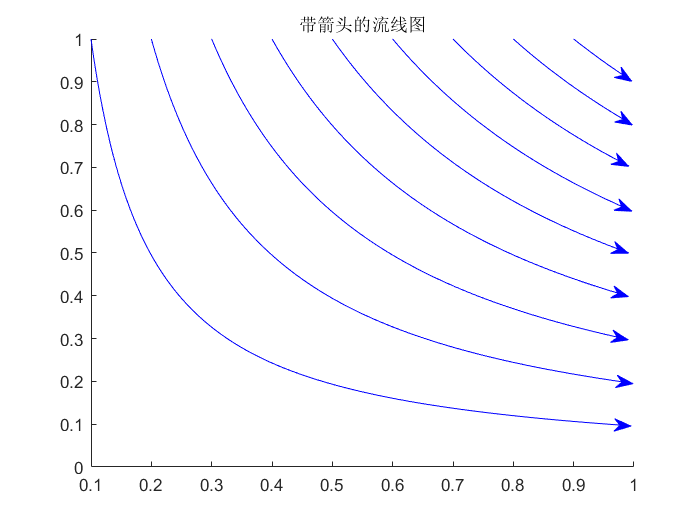

clear; clc;
% 直接把streamline函数的帮助文档 demo 拷贝过来 
[x, y] = meshgrid(0:0.1:1, 0:0.1:1);
u = x;
v = -y;
startx = 0.1:0.1:0.9;
starty = ones(size(startx));
% 需要获取所有流线的属性
lines = streamline(x, y, u, v, startx, starty);
% 下面开始画箭头，涉及到坐标的转换
% 获取 Axes 位置
posAxes = get(gca, 'Position');
posX = posAxes(1);
posY = posAxes(2);
width = posAxes(3);
height = posAxes(4);
% 获取 Axes 范围
limX = get(gca, 'Xlim');
limY = get(gca, 'Ylim');
minX = limX(1);
maxX = limX(2);
minY = limY(1);
maxY = limY(2);
% 遍历，逐条流线加箭头
for i = 1 : length(lines)
    % 获取每条流线的数据
    xData = lines(i).XData;
    yData = lines(i).YData;
    % 这里取的是最后两个点，一定要是相邻的两个点用来确定箭头方向
    x0 = xData(end-1 : end);
    y0 = yData(end-1 : end);
    % 转换坐标到相对于figure的坐标
    xNew = posX + (x0 - minX) / (maxX - minX) * width;
    yNew = posY + (y0 - minY) / (maxY - minY) * height;
    % 画箭头
    hold on
    annotation('arrow', xNew, yNew, 'color', 'b');
end
hold off
title('带箭头的流线图');